# Image-Based Defect Detection for Manufacturing Inspection

## Introduction

This project focuses on developing a reliable hybrid model to evaluate metal parts. Using a selected subset of the Metal Parts Defect Detection (MPDD) dataset, the system is designed to inspect images of metal plates and categorize them as either a "Pass" or a "Fail" based on visible scratches or rust. To get reliable results, the project builds a hybrid inspection system that combines a classical image processing function with an AI classifier. This approach allows our system to use the high accuracy of the AI for final decisions while using classical metrics to provide visual evidence and as a supportive fallback check.

## Task 1: Explore and Organize Image Dataset 

    For Task 1, our team explored the recommended datasets and found that the "Metal Parts Defect Detection Dataset (MPDD)" had the best images to use for our dataset. Instead of using the entire dataset, we only used a subset of the metal plate images in order to focus our defect detection pipeline onto a single part type. The images are labeled as "Pass", "Scratches", "Major Rust", and "Total Rust", with the last three defect types being considered as "Fail". This section of the .mlx loads the images in an image datastore to be used in the following tasks.

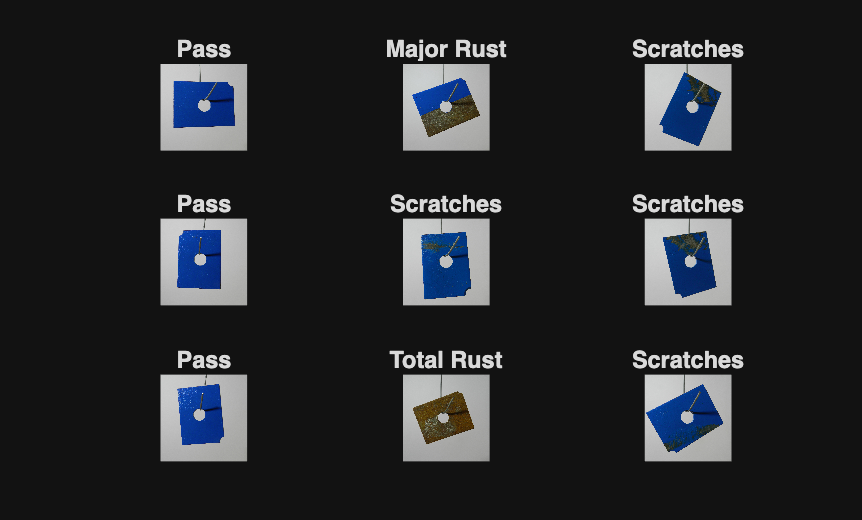

% Load dataset into partImgsds
% NOTE: Dataset folder must be in same folder as .mlx file (shouldn't be an
% issue if repository was cloned properly)
filepath = fileparts(matlab.desktop.editor.getActiveFilename);
dataFolder = fullfile(filepath, "Dataset"); 
partImgds = imageDatastore(dataFolder,'IncludeSubfolders',true,'LabelSource','foldernames');

% Store total number of images
numImg = length(partImgds.Labels);
% Display a random sample of images for inspection & to confirm dataset was
% properly loaded
idx = randperm(numImg,9);
for i = 1:9
    subplot(3,3,i)
    imshow(readimage(partImgds,idx(i)))
    title(string(partImgds.Labels(idx(i))))
end

## Task 2: Build a Single-Image Inspection Function

In Task 2, we built a single image inspection function that takes in an image from our chosen dataset and outputs the classical PASS/FAIL result, along with the evidence backing it. We split the inspection into 4 individual sections: standardization, preprocessing, segmentation, and metrics, before combining them all together under a single function. Images are first standardized into grayscale so metrics can be consistent across different samples, then preprocessed with Gaussian smoothing and contrast enhancement to make surface defects stand out better. The next step is segmentation which separates the part from the background and adds thresholding to find suspicious pixels inside the part. The last step is the analysis which produces three metrics: component count, largest defect area, and ratio of flagged pixels to total pixels. These metrics go through a threshold rule to reach a final PASS/FAIL decision. The main challenge in implementing this portion of the inspector was reliably processing the image in a specific order that would allow our analysis to output the intended results for each different defect. Our metrics also ended up overlapping between passing and failing parts, so we decided on the component count being the main decision variable. The function returns the metrics alongside the verdict so the reasoning behind the decision stays and can be compared to the AI classifier in task 3.

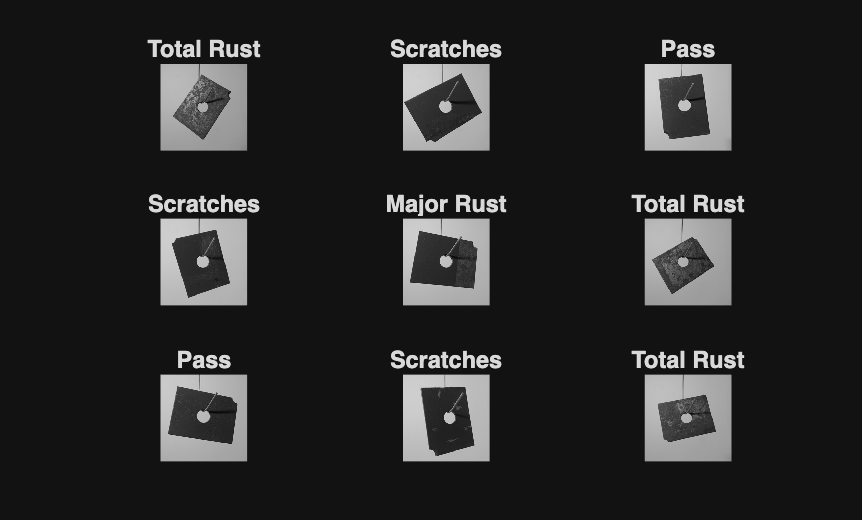

% Display a random sample of images to confirm standardization function
% works properly
idx = randperm(numImg,9);
for i = 1:9
    % Read random image from datastore
    img = readimage(partImgds,idx(i));
    
    % Apply standardization function to image
    img = standardizeImage(img);

    % Display image
    subplot(3,3,i)
    imshow(img)
    title(string(partImgds.Labels(idx(i))))
end



% Standardizes the image that is inputted to a standard size and grayscale
function img = standardizeImage(img)
    % Resize image to standard size
    img = imresize(img, [256, 256]);

    % Convert image from RGB to grayscale if needed
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
end


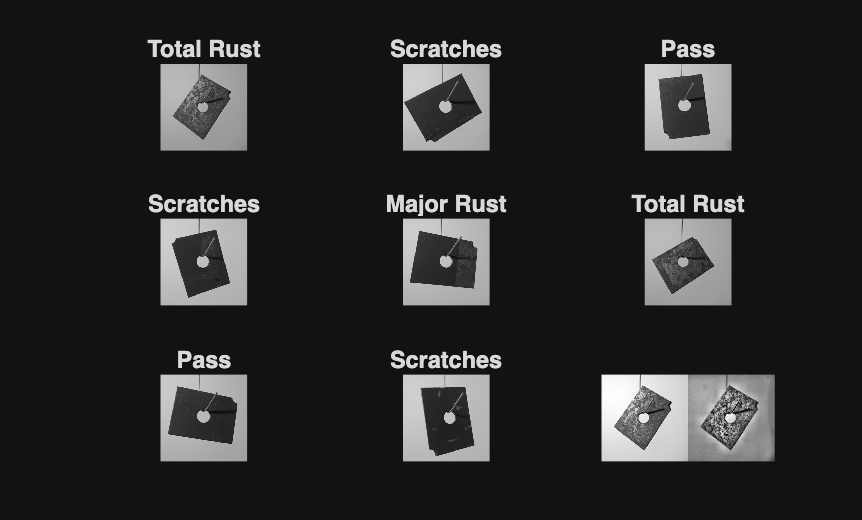

% Preprocessing

originalImg = readimage(partImgds, idx(1));
originalImg = standardizeImage(originalImg);

function img = preprocessImg(img)
    % Apply smoothing to reduce some small image noise
    img = imgaussfilt(img, 0.5);

    % increase contrast, defects pop out better
    img = adapthisteq(img, "ClipLimit", 0.03, "Distribution", "rayleigh");

end

processedImg = preprocessImg(originalImg);
imshowpair(originalImg, processedImg, "montage");

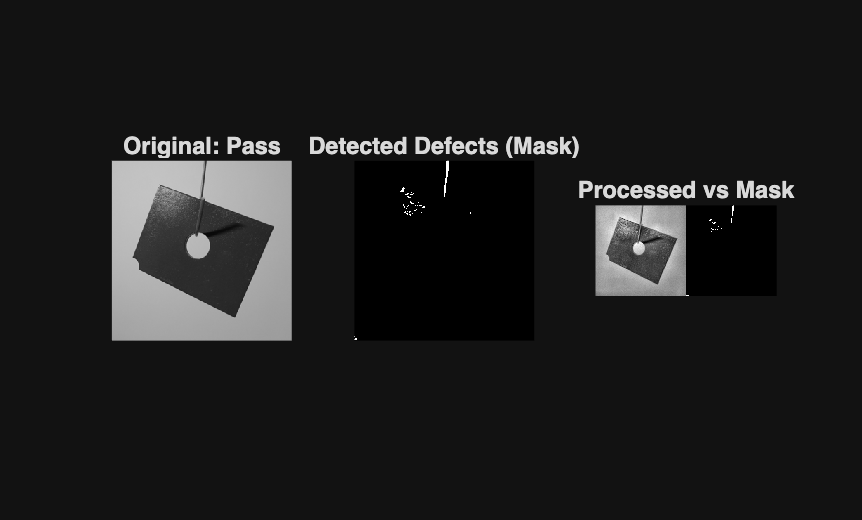



% ROI and Segmentation

function maskEvidence = defectEvidence(roi)
    
    % To separate the part from the background
    partMask = imbinarize(roi);
    partMask = ~partMask;

    % Neutralize the background
    maskedImg = roi;
    someValue = mean(maskedImg(partMask));
    maskedImg(imcomplement(partMask)) = someValue; % used imcomplement fcn to invert true output (white) to the defect

    % Smooth the pixels in the background
    smoothImg = imgaussfilt(maskedImg, 0.7);

    % Adaptive threshold 
    threshImg = adaptthresh(smoothImg,0.8);
    BW = imbinarize(threshImg);

    % Show only the defect inside the part
    BW = BW & partMask;
    
    % Identify and remove the hole in the plate from detection
    holeImg = regionprops(BW, 'Area', 'PixelIdxList');
    [maxArea,maxIndex] = max([holeImg.Area]); % finds the largest blob where the hole exists
    BW(holeImg(maxIndex).PixelIdxList) = false;
    
    maskEvidence = BW;
end


function metrics = quantifyDefects(maskEvidence, roi)
    
    cc = bwconncomp(maskEvidence); %find defect clusters
    numComponents = cc.NumObjects; %find amount of clusters
    
    props = regionprops(maskEvidence, 'Area'); %store the area of all clusters within array
    if isempty(props) %no clusters case
        maxArea = 0;
    else
        maxArea = max([props.Area]); %find defect/cluster with max area
end

areaRatio = nnz(maskEvidence) / numel(roi);
% find total pixels that are flagged as suspicious divided by
% total pixels in object to find the ratio of sus to not sus

metrics = struct(... %log metrics in structure
    'numComponents', numComponents, ...
    'maxArea', maxArea, ...
    'areaRatio', areaRatio ...
    );
end

% Single Image inspection function
function [baselineDecision, metrics, maskEvidence, processedImg] = inspectImage(I)
    stdImg        = standardizeImage(I);
    processedImg  = preprocessImg(stdImg);
    maskEvidence  = defectEvidence(processedImg);
    metrics       = quantifyDefects(maskEvidence, processedImg);
    baselineDecision = decideRules(metrics);
end

% --- TEST RUN SCRIPT ---
% 1. Pick a random image from your datastore
testIdx = randperm(numImg, 1);
rawImg = readimage(partImgds, testIdx);
trueLabel = string(partImgds.Labels(testIdx));

[baselineDecision, metrics, maskEvidence, processedImg] = inspectImage(rawImg);
stdImg = standardizeImage(rawImg);

% 6. Display results for visual confirmation
figure;
subplot(1, 3, 1);
imshow(stdImg);
title(sprintf("Original: %s", trueLabel));

subplot(1, 3, 2);
imshow(maskEvidence);
title("Detected Defects (Mask)");

subplot(1, 3, 3);
imshowpair(processedImg, maskEvidence, "montage");
title("Processed vs Mask");


% 7. Print metrics to the Command Window to inspect them
disp("--- Computed Defect Metrics ---");

--- Computed Defect Metrics ---


disp(metrics);

    numComponents: 36
          maxArea: 142
        areaRatio: 0.0046




% Fallback Decisions
function baselineDecision = decideRules(metrics)

    % Amax = 5000; % High value because area data is unreliable
    Nmax = 7; % More accurate value compared to area so it makes the PASS/FAIL decision
    
    if metrics.numComponents > Nmax
        baselineDecision = "FAIL";
    else
        baselineDecision = "PASS";
    end
end

% NOTE: Baseline rule thresholds are approximate 
% Classical metrics have major overlap between PASS and FAIL w/ this
% dataset; can only serve as a conservative check rather than preciseness

## Task 3: Train and Integrate an AI Classifier into your Single-Image Inspection Function

    For Task 3, our team implemented an AI Classifier by fine tuning the pretrained ResNet-18 network. A copy of the image datastore was made with the labels simplified to "Pass" and "Fail", and then the datastore was separated into a training and a testing image datastore. The network was trained using the Adam optimizer with a learning rate of 0.0001 for 10 epochs and a mini batch size of 32. During training, the testing datastore was used for validation, the training data was shuffled every epoch to improve generalization, and MATLAB's training progress window was used to monitor the model's performance. At the end of the training, MATLAB's training progress graph showed that the loss of the network was small, and from repeated testing the final training loss of the model would typically be 0.1 or less. After the network is trained, the classification function can be used, where the network and an image are passed in as arguments, and the AI network's classification and confidence score is returned. The classification function first ensures the image has the correct dimensions, then gets the result from the network and returns the classification and confidence score.

modelDir = fullfile(filepath, "Models");
if ~isfolder(modelDir), mkdir(modelDir); end
netFile  = fullfile(modelDir, "resnet18_binary_v1.mat"); % change name if want to train new model

if isfile(netFile) % remove if need new training
    % use previously trained network
    load(netFile, "net", "classNames", "trainingImgds", "testingImgds");
    disp("Loaded trained network");
else
    % Create a new dataset with binary labels of Pass and Fail for the AI
    % classifier
    binaryLabels = partImgds.Labels;
    binaryLabels(binaryLabels ~= "Pass") = "Fail";
    binaryLabels = removecats(binaryLabels);
    binaryImgds = imageDatastore(partImgds.Files);
    binaryImgds.Labels = categorical(binaryLabels);
    
    % Check number of images to confirm successful dataset creation
    countEachLabel(binaryImgds)
    % Split the dataset into a training set and testing set
    [trainingImgds, testingImgds] = splitEachLabel(binaryImgds, 0.8, 'randomized');
    
    % Check number of images in each set to confirm successful split, the
    % training set should have about 80% of the images from the binary dataset
    countEachLabel(trainingImgds)
    classNames = categories(trainingImgds.Labels);
    countEachLabel(testingImgds)
    % Load ResNet-18 and get the input size
    % NOTE: The add-on "Deep Learning Toolbox Model for ResNet-18 Network" must
    % be installed for this model to work
    net = imagePretrainedNetwork("resnet18", NumClasses = 2);
    inputSize = net.Layers(1).InputSize;
    
    % Create augmented image datasets for ResNet-18 to use
    augmentedTrainingImgds = augmentedImageDatastore(inputSize(1:2), trainingImgds);
    augmentedTestingImgds = augmentedImageDatastore(inputSize(1:2), testingImgds);
    
    % Set up the options for training the model
    options = trainingOptions("adam", InitialLearnRate = 0.0001, MaxEpochs = 10, MiniBatchSize = 32, ...
                              Shuffle = "every-epoch", ValidationData = augmentedTestingImgds, ...
                              Plots = "training-progress", Verbose = false);

    % Train the model
    net = trainnet(augmentedTrainingImgds, net, "crossentropy", options);

    % Save trained network so results are reproducable (can comment this out)
    save(netFile, "net", "classNames", "trainingImgds", "testingImgds");
end

Loaded trained network


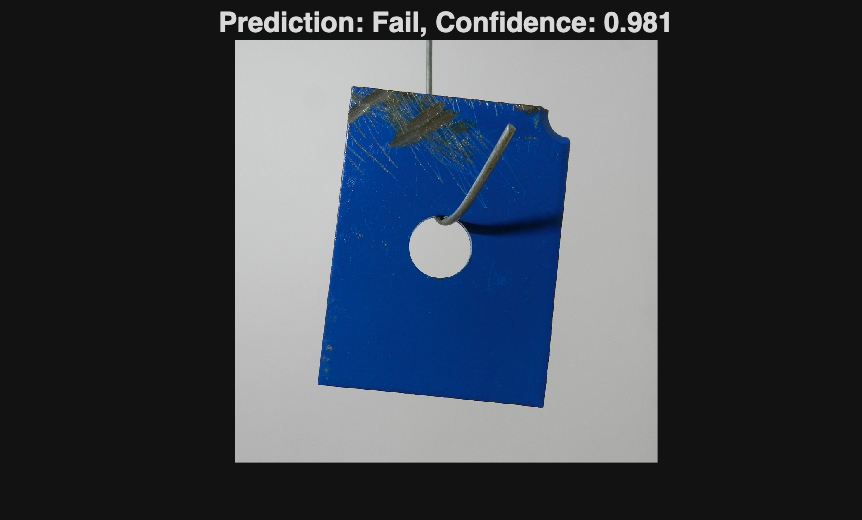


 


% Classification function, net is the trained AI model being used and
% roiForNet is the image being classified. The function will return Pass or
% Fail in aiLabel and the confidence percentage as a decimal (ex: 97% as
% 0.97) in aiScores
function [aiLabel, aiScores] = classify(net, roiForNet, classNames)
    % Change image specifications to ResNet-18's required specifications
    roiForNet = imresize(roiForNet, [244, 244]);
    if size(roiForNet, 3) == 1
        roiForNet = cat(3, roiForNet, roiForNet, roiForNet);
    end
    roiForNet = single(roiForNet);

    % Get the AI predictions for the chance of the image being a Pass and the
    % chance of the image being a Fail
    scores = predict(net, roiForNet);

    % The prediction with the highest percent is the returned prediction
    % along with the appropriate label
    [aiScores, index] = max(scores);
    aiLabel = string(classNames(index));
end

% Test classify function with a random image from the testing dataset
idx = randi(numel(testingImgds.Files));
testImg = readimage(testingImgds, idx);

[aiLabel, aiScore] = classify(net, testImg, classNames);
figure
imshow(testImg)
title("Prediction: " + string(aiLabel) + ", Confidence: " + string(round(aiScore, 3)))

## Task 3 Checkpoint: Combine outputs into a hybrid inspection result

In this part, we combined the two outputs from the classical inspection and the AI classifier into one unified result. The inspectPart function runs both methods on the same image, where the classical inspector produces its own verdict with supporting metrics, while the fine tuned AI classifier produces a label and confidence score. As the AI classifier proved to be more reliable on this dataset, we utilized it as the final decision maker and kept the classical output as a supporting check and to provide evidence for a certain verdict. If the two verdicts disagree, it will be flagged in the overlay alongside the final verdict and classical metric evidence on top of the input image. The result is an annotated image where a user can see the final decision with evidence and level of agreement behind it.

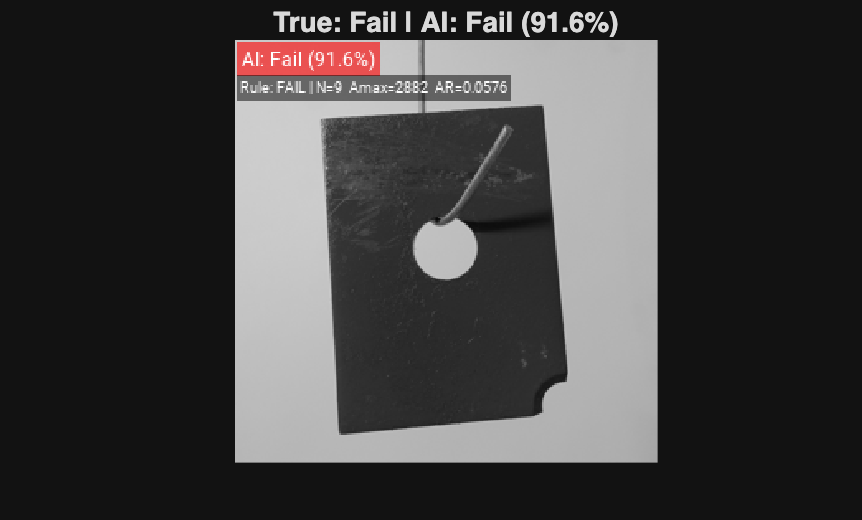

function [finalLabel, confidenceScore, evidenceOverlay, evidenceMetrics, ...
          baselineDecision, disagreementFlag] = inspectPart(I, net, classNames)

    % Original Image inspection
    [baselineDecision, evidenceMetrics, maskEvidence, ~] = inspectImage(I);
    stdImg    = standardizeImage(I);                   

    % AI decision, pass in raw image as its trained on RGB image
    [aiLabel, aiScore] = classify(net, I, classNames);
    finalLabel      = string(aiLabel);
    confidenceScore = double(aiScore);

    % Agreement check between original inspection and AI decision
    aiAsRule = upper(finalLabel);
    disagreementFlag = (aiAsRule ~= upper(string(baselineDecision)));

    % Evidence overlay on output image
    evidenceOverlay = buildOverlay(stdImg, maskEvidence, finalLabel, ...
                                   confidenceScore, baselineDecision, ...
                                   disagreementFlag, evidenceMetrics);
end


% Overlay function for inspection result on the image
function overlay = buildOverlay(grayImg, maskEvidence, finalLabel, score, ...
    baselineDecision, disagreementFlag, m)

    % Green is pass, red is fail
    if strcmpi(finalLabel, "Pass")
        boxColor = "green";
    else
        boxColor = "red";
    end

    overlay = repmat(im2uint8(grayImg), [1 1 3]);

    % AI result overlay
    txt = sprintf("AI: %s (%.1f%%)", finalLabel, 100*score);
    overlay = insertText(overlay, [2 2], txt, "BoxColor", boxColor, "BoxOpacity", 0.6, ...
        "TextColor", "white", "FontSize", 12);

    % Classical evidence overaly
    txt2 = sprintf("Rule: %s | N=%d  Amax=%d  AR=%.4f", baselineDecision, m.numComponents, m.maxArea, m.areaRatio);
    overlay = insertText(overlay, [2 22], txt2, "BoxColor", "black", "BoxOpacity", 0.5, ...
        "TextColor", "white", "FontSize", 9);

    % Overlay only if AI and classical evidence contradict
    if disagreementFlag
        overlay = insertText(overlay, [2 40], "Disagreement", "BoxColor", "yellow", "BoxOpacity", 0.8, ...
            "TextColor", "black", "FontSize", 10);
    end

end

% Testing

% Get a random image the network hasn't seen
idx = randi(numel(testingImgds.Files));
I   = readimage(testingImgds, idx);
trueLabel = string(testingImgds.Labels(idx));

[finalLabel, confidenceScore, evidenceOverlay, evidenceMetrics, ...
    baselineDecision, disagreementFlag] = inspectPart(I, net, classNames);

% Display
figure
imshow(evidenceOverlay)
title(sprintf("True: %s | AI: %s (%.1f%%)", trueLabel, finalLabel, 100*confidenceScore))

## Task 4: Evaluate Inspection System Performance

For Task 4, our team evaluated performance of our inspection system by developing a testing process. The test is ran through the runInspectionSuite function, which processes an entire batch of test images to gather comprehensive performance statistics. The script loops through all photos in the test datastore, passing each through the hybrid function and logging the true labels, predictions, confidence scores, and any AI-classical system disagreements into a structured results table.

Using this data, the function calculates the yield rate, defect rate, and overall system accuracy. To aid in visual comprehension, the system automatically generates a confusion matrix and a bar chart summarizing the batch results, along with a visual montage displaying any misclassified images to help identify common failure cases. During our clean test run, the hybrid system achieved perfect accuracy, and the script successfully reported that no classification errors were detected in the test batch.

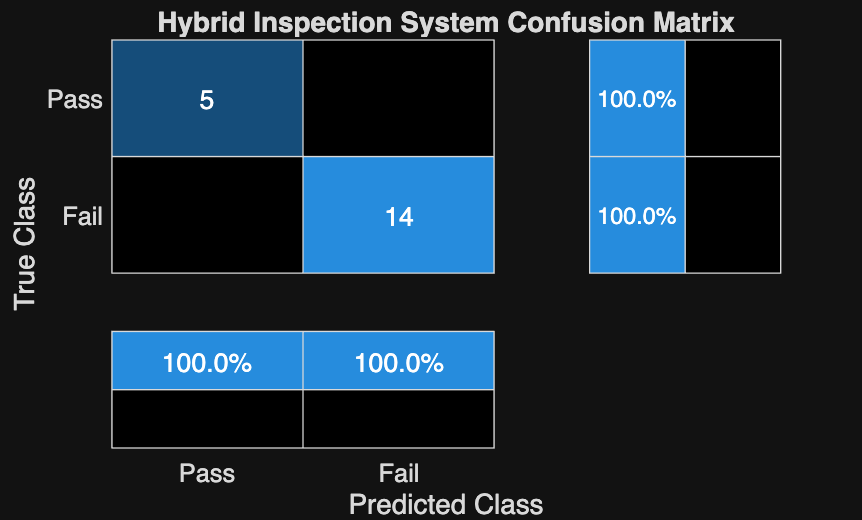

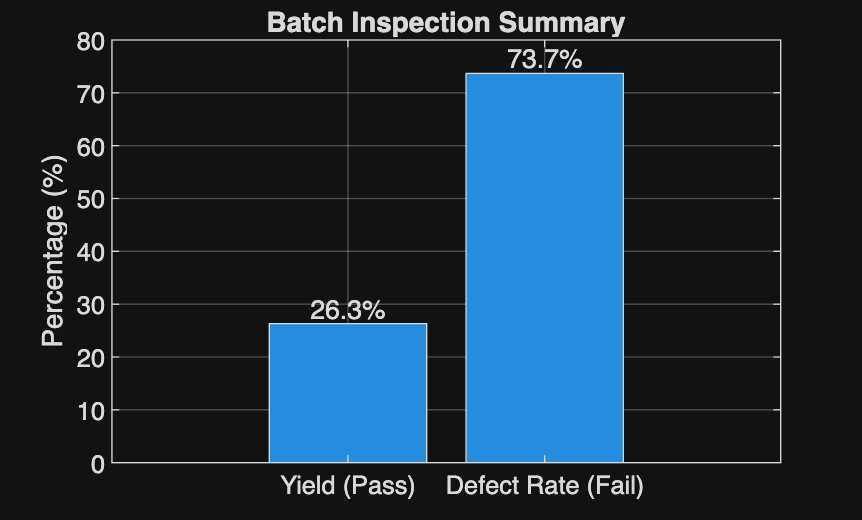

No classification errors were detected in this test batch!


% Run function on dataset
metrics = runInspectionSuite(net, testingImgds, classNames, false);


function metrics = runInspectionSuite(net, testDatastore, classNames, applyDistort)
    
    numImages = numel(testDatastore.Files);
    
    % Make arrays to store model testing statistics
    trueLabels= testDatastore.Labels;
    finalPreds= strings(numImages, 1);
    aiPreds = strings(numImages, 1);
    baselinePreds = strings(numImages, 1);
    scores= zeros(numImages, 1);
    disagreements = false(numImages, 1);
    overlayImages = cell(numImages, 1);

    % Loop through all photos in test batch
     for i = 1:numImages
        I = readimage(testDatastore, i);

        if applyDistort % For Task 5
            I = imgaussfilt(I,2); % Changes blur
            I = imnoise(I,"gaussian"); % Makes speckles 
        end

        %get metrics
        [finalLabel, confidenceScore, evidenceOverlay, ~, baselineDecision, disagreementFlag] = inspectPart(I, net, classNames);
        [aiLabel, ~] = classify(net, I, classNames);
        %log them in arrays
        finalPreds(i)    = finalLabel;
        aiPreds(i)       = string(aiLabel); % AI prediction
        baselinePreds(i) = string(baselineDecision);
        scores(i)        = confidenceScore;
        disagreements(i) = disagreementFlag;
        overlayImages{i} = evidenceOverlay;
    end

    % Format data to be processed in matrices
    classOrder    = string(classNames);
    trueLabels    = categorical(trueLabels, classOrder);
    finalPreds    = categorical(finalPreds, classOrder);
    aiPreds       = categorical(aiPreds, classOrder);
    baselinePreds = categorical(upper(baselinePreds), upper(classOrder));

    % Log Results into a Table
    resultsTable = table(testDatastore.Files, trueLabels, finalPreds, aiPreds, baselinePreds, ...
        scores, disagreements, ...
        'VariableNames', {'File', 'TrueLabel', 'FinalPrediction', 'AIPrediction', 'RulePrediction', 'Confidence', 'Disagreement'});

    % Calculate yield defect rate and accuracy
    numPass = sum(finalPreds == "Pass");
    numFail = sum(finalPreds == "Fail");
    
    metrics.TotalEvaluated = numImages;
    metrics.YieldRatePct   = (numPass / numImages) * 100;
    metrics.DefectRatePct  = (numFail / numImages) * 100;
    metrics.AccuracyPct    = mean(finalPreds == trueLabels) * 100;
    metrics.Disagreements  = sum(disagreements);

    metrics.resultsTable = resultsTable;

    % make confusion matrix
    figure('Name', 'Task 4: Confusion Matrix');
    confusionchart(trueLabels, finalPreds, ...
        'Title', 'Hybrid Inspection System Confusion Matrix', ...
        'RowSummary', 'row-normalized', ...
        'ColumnSummary', 'column-normalized');

    %Plot bar chart for yield and defect rates
    figure('Name', 'Task 4: Yield and Defect Metrics');
    b = bar([metrics.YieldRatePct, metrics.DefectRatePct]);
    set(gca, 'XTickLabel', {'Yield (Pass)', 'Defect Rate (Fail)'});
    ylabel('Percentage (%)');
    title('Batch Inspection Summary');
    grid on;
    text(1:2, [metrics.YieldRatePct, metrics.DefectRatePct], ...
        num2str([metrics.YieldRatePct; metrics.DefectRatePct], '%.1f%%'), ...
        'Vert', 'bottom', 'Horiz', 'center');

    % make montage to find common failures
    errorIdx = find(finalPreds ~= trueLabels);
    
    if ~isempty(errorIdx)
        figure('Name', 'Task 4: Failure Cases Montage');
        montage(testDatastore.Files(errorIdx), 'Size', [NaN, 4]);
        title(sprintf('Inspection Failure Cases (Total Misclassified: %d)', numel(errorIdx)));
    else
        fprintf('No classification errors were detected in this test batch!\n');
    end
end


## Task 5: Test and Evaluate System Robustness

To test the robustness of our image classifier, we chose to add noise and blur to our images because our classic evidence system already has small detection issues with contrast and lighting. When comparing the simulated variation with the clean function, we found the false-reject rate rose from 0% to 40% consistently. These percentages mean the classical evidence process became more prone to flagging good parts as defective once noise was introduced, while the AI classifier's accuracy only dropped by 10.5 points.

No classification errors were detected in this test batch!


% Distorted
metricsDistort = runInspectionSuite(net, testingImgds, classNames, true); % "true" will pass data through applyDistort

% Compare false rejects
passIdx_clean = (metrics.resultsTable.TrueLabel == "Pass"); % Clean 
falseRejects_clean = sum(metrics.resultsTable.FinalPrediction(passIdx_clean) == "Fail");
totalPass_clean = sum(passIdx_clean);
falseRejectRate_clean = (falseRejects_clean / totalPass_clean) * 100;

passIdx_distort = (metricsDistort.resultsTable.TrueLabel == "Pass"); % Distorted
falseRejects_distort = sum(metricsDistort.resultsTable.FinalPrediction(passIdx_distort) == "Fail");
totalPass_distort = sum(passIdx_distort);
falseRejectRate_distort = (falseRejects_distort / totalPass_distort) * 100;

fprintf("False-reject rate — Clean: %.1f%%, Distorted: %.1f%%\n", ...
    falseRejectRate_clean, falseRejectRate_distort);

False-reject rate — Clean: 0.0%, Distorted: 0.0%



accDrop = metrics.AccuracyPct - metricsDistort.AccuracyPct;
fprintf("Accuracy dropped by %.1f percentage points under distortion.\n", accDrop);

Accuracy dropped by 0.0 percentage points under distortion.



frrIncrease = falseRejectRate_distort - falseRejectRate_clean;
fprintf("False-reject rate increased by %.1f percentage points under distortion.\n", frrIncrease);

False-reject rate increased by 0.0 percentage points under distortion.


## Interpretation of Results

The false-reject rate increased more sharply than the overall accuracy decline which suggests that the classical evidence pipeline, not the AI Classifier, is the system's primary source of sensitivity to image noise and blur. In the decideRules function, the system relies on fixed thresholds for maxArea and numComponents, so small shifts in data from detected noise (speckles remaining after bwareaopen) or any blur from areaRatio are enough for the classifier to change borderline Passes to Fail. However, if the AI classifier was working alone, it is able to predict Pass or Fail correctly. This suggests the rule-based fallback switches interpretability for robustness.

One limitation of our work is that our baseline rule thresholds are approximate rather than precisely tuned. The classical metrics (maxArea, numComponents, areaRatio) show a lot of overlap between Pass and Fail part in this dataset, so a fixed cutoff couldn't cleanly separate the two classes. This is why we set the area threshold high to only catch significant outliers, while the numComponents could be a little more precise. Another limitation is the hook feature present in every image of our dataset. This would often get picked up as false-positive evidence by our segmentation. We were able to filter out the holes in the center of the plate fairly reliably, but we didn't get to a solution for filtering the hook the same way, so it still serves an occasional source of error in the evidence mask.

The next step we would take with this defect system would be to better tune the rule-based thresholds using a larger or more balanced dataset, so our maxArea and numComponents cutoffs actually separate Pass and Fail parts. This could also involve testing a range of threshold values to find where false rejects and false accepts are best balanced instead of picking one fixed number. Another next step would be to improve the segmentation step so the hook isn't picked up as false-positive evidence. This might mean adding a fixed ROI or mask that excludes the hook region, since its position stays pretty consistent across the images. Despite some compatibility issues with the lighting/contrast distortions accepting color images, it would be useful to go back and get this specific distortion working to test the full range of station variation.